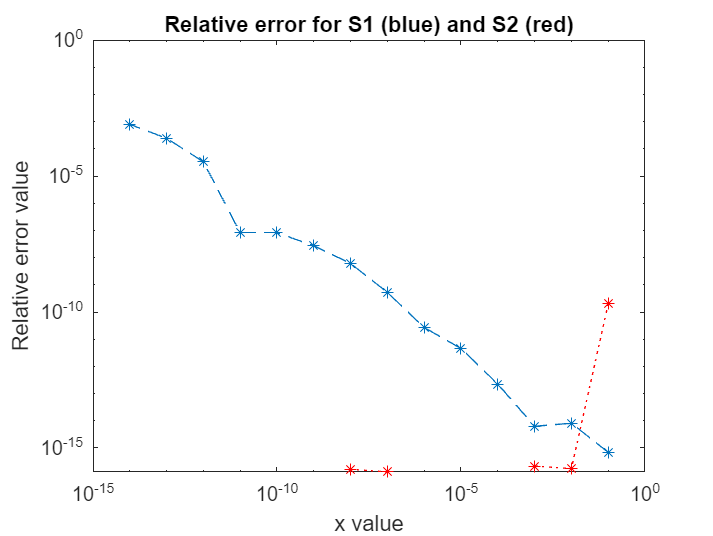

clear

% Define arrays to be used
% The expression arrays are not really needed
xarray = zeros(14, 1);
y = zeros(14, 1);
s1 = zeros(14, 1);
s2 = zeros(14, 1);
rel_err_s1 = zeros(14, 1);
rel_err_s2 = zeros(14, 1);

% Calculate the relative error for every x from x = 10^-1 to 10^-14.
for i = 1:14
    xarray(i) = 10^(-i);
    x = xarray(i);

    % Use the expressions for the given x value
    y(i) = sinh(x);
    s1(i) = (exp(x)-exp(-x))/2;
    s2(i) = (x + (x^3)/factorial(3) + (x^5)/factorial(5));

    % Calculate relative errors for S1 and S2
    rel_err_s1(i) = (abs(s1(i) - y(i))) / abs(y(i));
    rel_err_s2(i) = (abs(s2(i) - y(i))) / abs(y(i));
end

% Logarithmic plot of the relative errors for S1 and S2
loglog(xarray, rel_err_s1, "--*");
title('Relative error for S1 (blue) and S2 (red)')
xlabel('x value')
ylabel('Relative error value') 
hold on
loglog(xarray, rel_err_s2, "r:*");


% S1 has worse accuracy for large negative values of x
% S2's accuracy becomes better for large negative values
% S1 worse accuracy because of cancellation